# Design controllers

clear all
close all
clc

load modello_j1.mat
load modello_j2.mat

s=tf('s');
p1=[modello_continuo_tf_j1/s;
    modello_continuo_tf_j1]

p1 =
 
  From input "u1" to output...
                                                           
         0.1988 s^6 + 3.037 s^5 + 2077 s^4 + 1.705e04 s^3  
                                                           
                     + 5.432e05 s^2 - 1.965e06 s + 3.391e07
                                                           
   y1:  -----------------------------------------------------
                                                             
        s^8 + 60.9 s^7 + 5.025e04 s^6 + 9.595e05 s^5         
                                                             
                + 1.615e07 s^4 + 1.352e08 s^3 + 8.368e08 s^2 
                                                             
                                                 + 16.91 s   
                                                             
 
                                                          
        0.1988 s^6 + 3.037 s^5 + 2077 s^4 + 1.705e04 s^3  
                                              

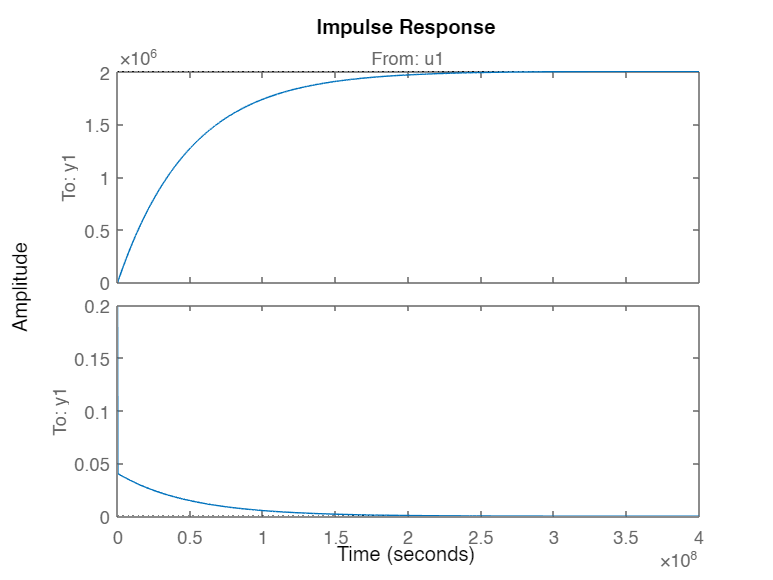

impulse(p1)


p2=[modello_continuo_tf_j2/s;
    modello_continuo_tf_j2]

p2 =
 
  From input "u1" to output...
                                                             
        0.5156 s^6 + 9.215 s^5 + 1.284e04 s^4 + 2.714e05 s^3 
                                                             
                    + 3.941e06 s^2 + 3.264e07 s + 2.091e07   
                                                             
   y1:  -----------------------------------------------------
                                                             
        s^8 + 83.88 s^7 + 9.228e04 s^6 + 3.178e06 s^5        
                                                             
                + 5.443e07 s^4 + 8.668e08 s^3 + 5.378e09 s^2 
                                                             
                                              + 4.746e10 s   
                                                             
 
                                                             
        0.5156 s^6 + 9.215 s^5 + 1.284e04 s^4 + 2.714e05 s^3 
                              

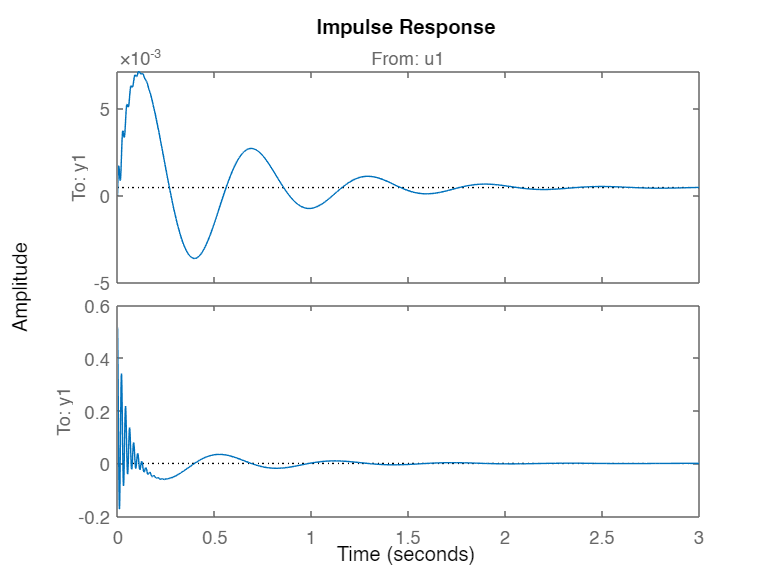

impulse(p2)

P = p1(1);

La cifra di merito è


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


(alternativa $J=-\omega_c$ massimizzare la pulsazione di taglio)

con $\omega_c$ la frequenza (pulsazione) di taglio, e $\omega_{c,des}$ il valore desiderato.

wc_des=70;
J=@(x)pidvel_cost_function(x,P,wc_des);

Le incognite del problema sono $x=[K_p,\;K_i,\;K_d,\;T_f]$

I vincoli sono (potete modificarli, aggiungerne, toglierne)

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

MS=1.4;
wh=2000;    % banda desiderata anello chiuso
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;
PM_min=60;

w_vector=logspace(-2,4,1e3)'; % [10^0,10^4]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pidvel_constraints(x,P,w_vector,MS,wh,Fh_max,wl,Dh_max,PM_min);

Risolvo il problema con GlobalSearch, la soluzione è *globale*.

gs = GlobalSearch('Display','iter');
x0=[1,1,0,10];

problem = createOptimProblem('fmincon','x0',x0,...
    'objective',J,'lb',[0.01,0.01,0,0.001],'ub',[10000,10000,10000,100],'nonlcon',nlcon);
x = run(gs,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      686        4687    

Kp=x(1);
Ki=x(2);
Kd=x(3);
Tf=x(4);
s=tf('s');
C=Kp+Ki/s+Kd*s/(Tf*s+1);

figure(1)
margin(C*P)
figure(2)
%MS=max(S)=max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(C*sys_vel_carico)
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/MS*sin(angolo),1/MS*cos(angolo),'--k')
hold off
xlim([-5 5])
ylim([-5 5])
